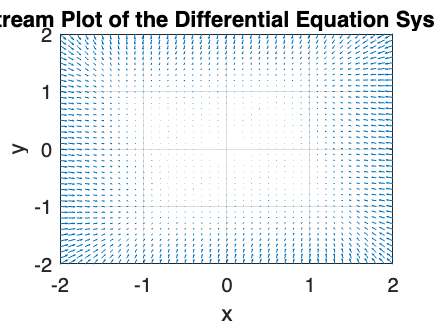

% Define the parameters and grid
a = 1;
[x, y] = meshgrid(-2:0.1:2, -2:0.1:2);

% Define the system of differential equations
xdot = a * x - y - 2 * x.^3;
ydot = x + a * y - 2 * y.^3;

% Create a stream plot
figure;
quiver(x, y, xdot, ydot);
xlabel('x');
ylabel('y');
title('Stream Plot of the Differential Equation System');
axis tight;
grid on;

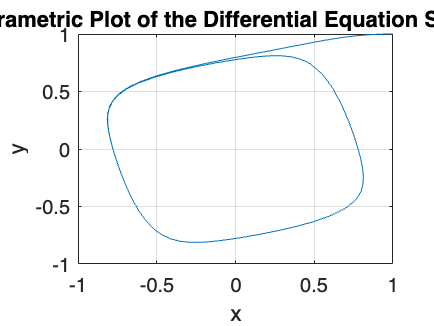


% Define the parameters
a = 1; % You can change the value of 'a' as needed

% Define the system of differential equations as function handles
ode_system = @(t, z) [a*z(1) - z(2) - 2*z(1)^3; z(1) + a*z(2) - 2*z(2)^3];

% Set the initial conditions
tspan = [0, 10]; % Time span for the simulation
initial_conditions = [1; 1]; % Initial values of x and y

% Solve the system of ODEs using ode45
[t, z] = ode45(ode_system, tspan, initial_conditions);

% Extract the solutions for x and y
x = z(:, 1);
y = z(:, 2);

% Create a parametric plot
figure;
plot(x, y);
xlabel('x');
ylabel('y');
title('Parametric Plot of the Differential Equation System');
grid on;
hold on;